#  Analysis 1

side by side gem vs cdt1 in different cycling conditions

## Load data

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\C241_Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'NR45 DMSO',2:3 ,2:3,1:25,[0 0 0],[0 10]; %1    
        'NR45 DOX',2:3 ,5:6,1:25,[0 0 0],[0 10]; %1
        'NR79 DMSO',4:5 ,2:3,1:25,[0 0 0],[0 10]; %1
        'NR79 DOX',4:5 ,5:6,1:25,[0 0 0],[0 10]; %1
        'NR80 DMSO',6:7 ,2:3,1:25,[0 0 0],[0 10]; %1
        'NR80 DOX',6:7,5:6,1:25,[0 0 0],[0 10]; %1
    };


% load([dataDir 'sensordata.mat'],'S');
S = loadData_IF(conditions, dataDir);


**Compare histograms of Cdt1 no release**

conds = [1 2];
data = {};
for i=1:length(conds)
    condition=conds(i);
    yval = 'FarRed1';
    
    ydata = log2(S(condition).(yval)); %.*S(condition).area);
%     inds = ydata > 0.5 & ydata < 2.5;
%     
%     ydata = ydata(inds);
    data = [data {ydata}];
end

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(2))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','FontSize',16)

ans = 1×2 cell array
    {'Plot #1: '}    {'Plot #2: '}


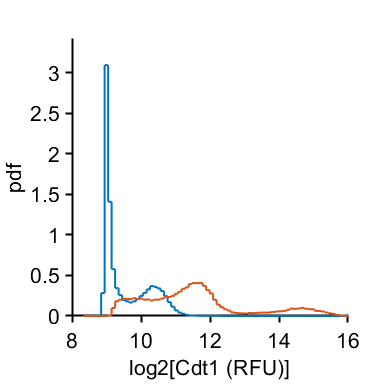

xlabel('log2[Cdt1 (RFU)]')
axis square
xlim([8 16])
% pbaspect([2.5 1 1])
print_pdf([pwd() '\Figs\NR45_compare.pdf'])

data

data = 1×2 cell array
    {64867×1 double}    {50486×1 double}


**Compare histograms of Cdt1 no release**

conds = [3 4];
data = {};
for i=1:length(conds)
    condition=conds(i);
    yval = 'FarRed1';
    
    ydata = log2(S(condition).(yval)); %.*S(condition).area);
%     inds = ydata > 0.5 & ydata < 2.5;
%     
%     ydata = ydata(inds);
    data = [data {ydata}];
end

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(2))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','FontSize',16)

ans = 1×2 cell array
    {'Plot #1: '}    {'Plot #2: '}


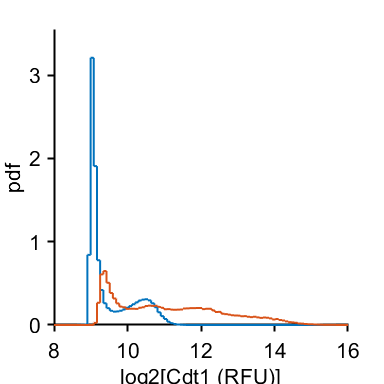

xlabel('log2[Cdt1 (RFU)]')
axis square
xlim([8 16])
% pbaspect([2.5 1 1])
print_pdf([pwd() '\Figs\NR79_compare.pdf'])

data

data = 1×2 cell array
    {94688×1 double}    {82913×1 double}


**Compare histograms of Cdt1 no release**

conds = [5 6];
data = {};
for i=1:length(conds)
    condition=conds(i);
    yval = 'FarRed1';
    
    ydata = log2(S(condition).(yval)); %.*S(condition).area);
%     inds = ydata > 0.5 & ydata < 2.5;
%     
%     ydata = ydata(inds);
    data = [data {ydata}];
end

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(2))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','FontSize',16)

ans = 1×2 cell array
    {'Plot #1: '}    {'Plot #2: '}


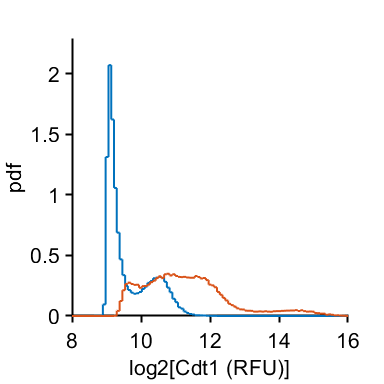

xlabel('log2[Cdt1 (RFU)]')
axis square
xlim([8 16])
% pbaspect([2.5 1 1])
print_pdf([pwd() '\Figs\NR80_compare.pdf'])

data

data = 1×2 cell array
    {91255×1 double}    {70994×1 double}


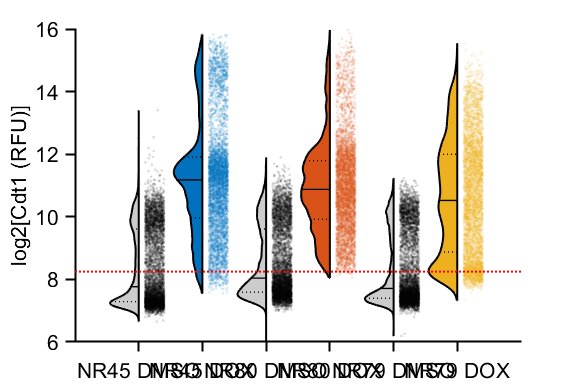

% colors = [0 113 188; 193 39 45; 77,175,74]/255;
colors = lines(3);
colors = [colors; 0 0 0];
cols = {[.8 .8 .8],colors(1,:),[.8 .8 .8],colors(2,:),[.8 .8 .8],colors(3,:)}';
groupcol = colors([4 1 4 2 4 3],:);

conds = [1 2 5 6 3 4]; %Cdt1 dox-, Cdt1 dox+, Cdt1delCy dox-, Cdt1delCy dox+, Cdt1delpip dox-, Cdt1delpip dox+
data = {};
ally=[];
group=[];
for i=1:length(conds)
    condition=conds(i);
    yval = 'FarRed1';
    
    ydata = S(condition).(yval); %.*S(condition).area);
    ydata = ydata(ydata>2^8.5);
    ydata = ydata - 2^8.5;
    ydata = log2(ydata);
    ydata = randsample(ydata,5000,false);
    data = [data {ydata}];
    ally = [ally; ydata];
    group = [group;repmat(i,size(ydata))];
end

figure('Units', 'Inches', 'Position', [0, 0, 6, 4])
% h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
%     'xNames',names);
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.15);
ylabel([ 'log2[Cdt1 (RFU)]'])
hline(8.25)
% xticks([2 5 8 11 14])
xticklabels(conditions(conds,1))
ylim([6 16])
% xtickangle(45)


% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\stain_compare_cdt1_mutant.pdf'])